Problem 2

1) RK-4 would be an appropriate choice because the stability region of RK4 intersects with the imginary axis, so it seems to be a good idea to solve the advection since the eigenvalues are purely imaginary.

2) Implementation: RK4 with T=1, and dx = 0.01;

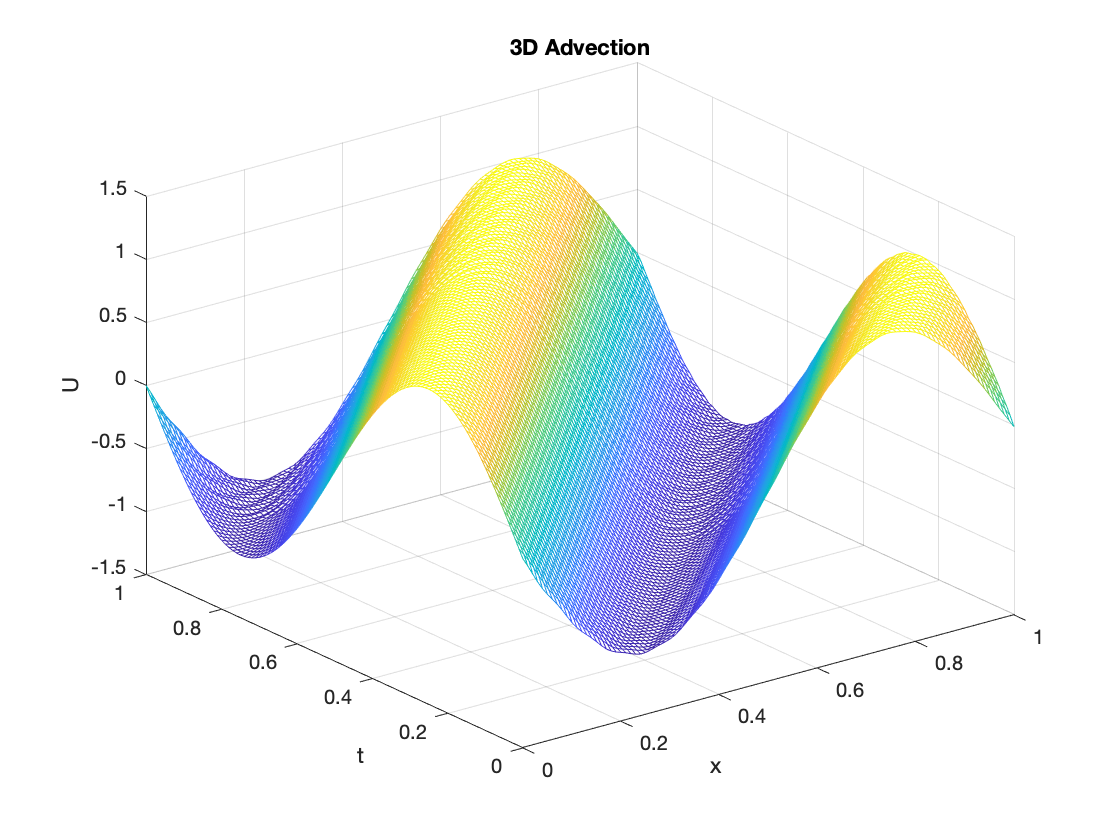

T = 1;
dx = 0.01;
xspan = 0:dx:1;
m = length(xspan);
% suppose we have 100 time steps
n = 100;
dt = T/n;
tspan = 0:dt:T;
u0 = @(x) sin(2*pi.*x);
U = zeros(m,n+1);
U(:,1) = u0(xspan); % initial condition, t = 0

Y1 = zeros(m,1);
Y2 = zeros(m,1);
Y3 = zeros(m,1);
Y4 = zeros(m,1);
Unew = zeros(m,1);

for j = 1:n
    Y1 = U(:,j);

    Y2(2:m-1) = Y1(2:m-1) + dt/2*(-(Y1(3:m)-Y1(1:m-2))/(2*dx));
    Y2(1) = Y1(1) + dt/2*((Y1(2)-Y1(m-1))/(2*dx));
    Y2(m)=Y2(1);
    

    Y3(2:m-1) = Y1(2:m-1) + dt/2*(-(Y2(3:m)-Y2(1:m-2))/(2*dx));
    Y3(1) = Y1(1) + dt/2*(-(Y2(2)-Y2(m-1))/(2*dx));
    Y3(m)=Y3(1); 
    

    Y4(2:m-1) = Y1(2:m-1) + dt*(-(Y3(3:m)-Y3(1:m-2))/(2*dx));
    Y4(1) = Y1(1) + dt*(-(Y3(2)-Y3(m-1))/(2*dx));
    Y4(m)=Y4(1);
    
    Unew(1) = U(1,j) + dt/6*((-(Y1(2)-Y1(m-1))/(2*dx))+...
        2*(-(Y2(2)-Y2(m-1))/(2*dx))+...
        2*(-(Y3(2)-Y3(m-1))/(2*dx))+(-(Y4(2)-Y4(m-1))/(2*dx)));  
    Unew(2:m-1) = U(2:m-1,j) + dt/6*((-(Y1(3:m)-Y1(1:m-2))/(2*dx))+...
        2*(-(Y2(3:m)-Y2(1:m-2))/(2*dx))+...
        2*(-(Y3(3:m)-Y3(1:m-2))/(2*dx))+(-(Y4(3:m)-Y4(1:m-2))/(2*dx)));

    Unew(m)=Unew(1);
    
    U(:,j+1)=Unew;
end
% Generate a 3D graph
figure(1);
mesh(xspan,tspan,U(:,:))
xlabel('x')
ylabel('t')
zlabel('U')
title("3D Advection")

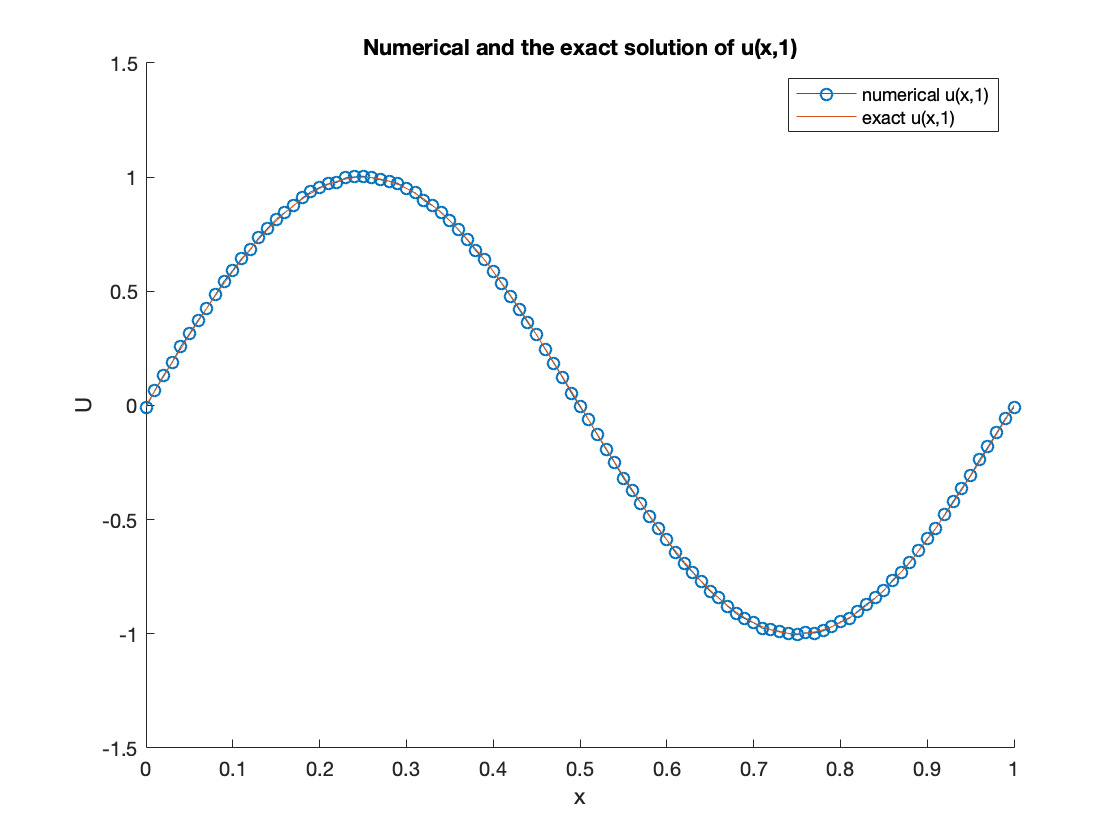

% Graph u(x,1) on a plane
figure(2);
hold off;
hold on;
plot(xspan,U(:,end),'-o')
plot(xspan, u0(xspan-T)) % Exact solution u0(x-T)
legend('numerical u(x,1)','exact u(x,1)')
title("Numerical and the exact solution of u(x,1)")
xlabel('x')
ylabel('U')
hold off;

3) BDF may not be a good idea. Although the stability region covers a part of the imaginary axis, and the stability region is very large, the method is very complicated to be implemented since the method is implicit. 